### Bridge of Doom Project

clc, clear all

% define variables
syms u

% beta * t = u
% lower beta = lower speed
beta = 0.1;
timeBounds = [0 (3.2/beta)];

% Define equations
r = 4*[0.396*cos(2.65*(beta*u+1.4));...
   -0.99*sin(beta*u+1.4);...
   0];

% Assume u is positive
assume(u,{'real','positive'})

% ---- FIND UNIT TANGENT VECTOR ----
dr=diff(r,u);
T_hat=simplify(dr./norm(dr))

$$T\_hat = \begin{array}{l} \left(\begin{array}{c} -\frac{53\,\sin\left(\frac{53\,u}{200}+\frac{371}{100}\right)}{\sigma_{1}}\\ -\frac{50\,\cos\left(\frac{u}{10}+\frac{7}{5}\right)}{\sigma_{1}}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(\frac{u}{10}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,u}{200}+\frac{371}{100}\right)}^{2}} \end{array}$$


% ---- FIND UNIT NORMAL VECTOR----
dT_hat=diff(T_hat,u);
N_hat=dT_hat/norm(dT_hat);
N_hat=simplify(N_hat)

$$N\_hat = \begin{array}{l} \left(\begin{array}{c} -\frac{2\,\left(96725\,\sigma_{6}+140450\,\sigma_{5}+43725\,\sigma_{4}\right)}{\sigma_{1}}\\ \frac{112360\,\sin\left(\frac{u}{10}+\frac{7}{5}\right)+205057\,\sigma_{3}+92697\,\sigma_{2}}{\sigma_{1}}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=53\,\sqrt{2500\,{\left(73\,\sigma_{6}+106\,\sigma_{5}+33\,\sigma_{4}\right)}^{2}+2809\,{\left(40\,\sin\left(\frac{u}{10}+\frac{7}{5}\right)+73\,\sigma_{3}+33\,\sigma_{2}\right)}^{2}}\\ \sigma_{2}=\sin\left(\frac{63\,u}{100}+\frac{441}{50}\right)\\ \sigma_{3}=\sin\left(\frac{43\,u}{100}+\frac{301}{50}\right)\\ \sigma_{4}=\cos\left(\frac{93\,u}{200}+\frac{651}{100}\right)\\ \sigma_{5}=\cos\left(\frac{53\,u}{200}+\frac{371}{100}\right)\\ \sigma_{6}=\cos\left(\frac{13\,u}{200}+\frac{91}{100}\right) \end{array}$$


% ---- FIND VELOCITY ----
speed = simplify(norm(dr))

$$speed = \frac{99\,\sqrt{2500\,{\cos\left(\frac{u}{10}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,u}{200}+\frac{371}{100}\right)}^{2}}}{12500}$$


% ---- FIND ANGULAR VELOCITY ----
angular_velocity = simplify(cross(T_hat,dT_hat))

$$angular\_velocity = \left(\begin{array}{c} 0\\ 0\\ -\frac{3869\,\cos\left(\frac{33\,u}{200}+\frac{231}{100}\right)+1749\,\cos\left(\frac{73\,u}{200}+\frac{511}{100}\right)}{10000\,\cos\left(\frac{u}{5}+\frac{14}{5}\right)-11236\,\cos\left(\frac{53\,u}{100}+\frac{371}{50}\right)+21236} \end{array}\right)$$

### Left and Right Wheel Velocities

% ---- FIND WHEELs ----
% since angular velocity is always in k hat directly only,
% multiplying norm(angular_velocity) with sign(angular_velocity)
% is the same as the dot product of angular velocity with k hat

d = 0.235;
v_left_wheel = speed - d/2*angular_velocity(3);
v_right_wheel = speed + d/2*angular_velocity(3);

$$v\_left\_wheel = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{1} & \sigma_{1} & \sigma_{1}+\frac{47\,\left|11607\,\sigma_{4}+5247\,\sigma_{2}\right|\,\mathrm{sign}\left(\frac{73\,\sigma_{4}+33\,\sigma_{2}}{2500\,\sigma_{5}-2809\,\sigma_{3}+5309}\right)}{400\,\left(10000\,\sigma_{5}-11236\,\sigma_{3}+21236\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{297\,\sqrt{2500\,{\cos\left(\frac{3\,u}{10}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{159\,u}{200}+\frac{371}{100}\right)}^{2}}}{12500}\\ \sigma_{2}=\cos\left(\frac{219\,u}{200}+\frac{511}{100}\right)\\ \sigma_{3}=\cos\left(\frac{159\,u}{100}+\frac{371}{50}\right)\\ \sigma_{4}=\cos\left(\frac{99\,u}{200}+\frac{231}{100}\right)\\ \sigma_{5}=\cos\left(\frac{3\,u}{5}+\frac{14}{5}\right) \end{array}$$

$$v\_right\_wheel = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{1} & \sigma_{1} & \sigma_{1}-\frac{47\,\left|11607\,\sigma_{4}+5247\,\sigma_{2}\right|\,\mathrm{sign}\left(\frac{73\,\sigma_{4}+33\,\sigma_{2}}{2500\,\sigma_{5}-2809\,\sigma_{3}+5309}\right)}{400\,\left(10000\,\sigma_{5}-11236\,\sigma_{3}+21236\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{297\,\sqrt{2500\,{\cos\left(\frac{3\,u}{10}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{159\,u}{200}+\frac{371}{100}\right)}^{2}}}{12500}\\ \sigma_{2}=\cos\left(\frac{219\,u}{200}+\frac{511}{100}\right)\\ \sigma_{3}=\cos\left(\frac{159\,u}{100}+\frac{371}{50}\right)\\ \sigma_{4}=\cos\left(\frac{99\,u}{200}+\frac{231}{100}\right)\\ \sigma_{5}=\cos\left(\frac{3\,u}{5}+\frac{14}{5}\right) \end{array}$$

### Define linspace for u for plotting

% define 100evenly spaced points between 0 and 3.2
u_num = linspace(0,3.2/beta,100); 

### Plot Bridge Centerline and Vectors

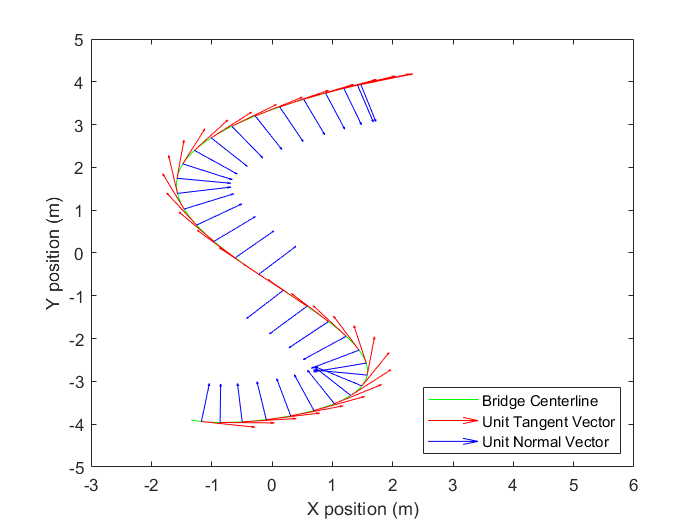

clf;
% plot the centerline
r_num(1,:)=double(subs(r,[u],[u_num(1)]));
plot(r_num(:,1),r_num(:,2),'g'),axis([-3 6 -5 5]),hold on % plot the entire curve

%we will also convert to a number of type double
for i=1:length(u_num)
    T_hat_num(i,:)=double(subs(T_hat,[u],[u_num(i)]));
    N_hat_num(i,:)=double(subs(N_hat,[u],[u_num(i)]));

    % plot the vectors less frequently
     if mod(i, 3) == 0 || i == length(u_num)
         quiver(r_num(i,1),r_num(i,2),T_hat_num(i,1),T_hat_num(i,2),'r') % plot the unit tangent
         quiver(r_num(i,1),r_num(i,2),N_hat_num(i,1),N_hat_num(i,2),'b') % plot the unit normal
     end
end
drawnow
xlabel('X position (m)')
ylabel('Y position (m)')
legend('Bridge Centerline', 'Unit Tangent Vector', 'Unit Normal Vector','Location','southeast')

### Load csv

data = readtable("bod_data.csv", "Delimiter", ",");
data_size = size(data, 1);
data.time = data.time - data.time(1);

data_time = (data.time ./ data.time(data_size)) * (3.2/beta)

data_time =          0
    0.1020
    0.2030
    0.2980
    0.4009
    0.5019
    0.6019
    0.7029
    0.8019
    0.9039



v_left_actual = zeros(data_size);
v_right_actual = zeros(data_size);
speed_actual = zeros(data_size);
angular_velocity_actual = zeros(data_size);

for i=1:(data_size - 1)
    v_left_actual(i) = (data.encoderLeft(i+1) - data.encoderLeft(i))/(data.time(i+1) - data.time(i));
    v_right_actual(i) = (data.encoderRight(i+1) - data.encoderRight(i))/(data.time(i+1) - data.time(i));
    speed_actual(i) = (v_left_actual(i) + v_right_actual(i))/2;
    angular_velocity_actual(i) = (v_right_actual(i) - v_left_actual(i))/2;
end

### Plot Speed

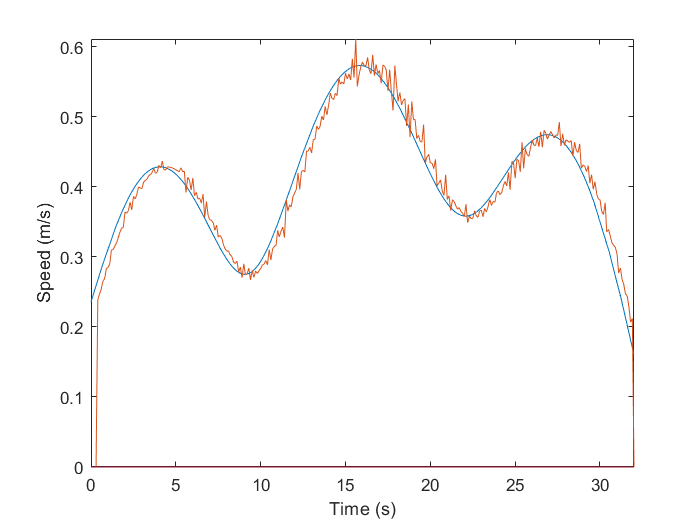


clf;
fplot(speed,[0 3.2/beta]); hold on;
plot(data.time, speed_actual, '-');
xlabel('Time (s)')
ylabel('Speed (m/s)')

### Plot Angular Velocity

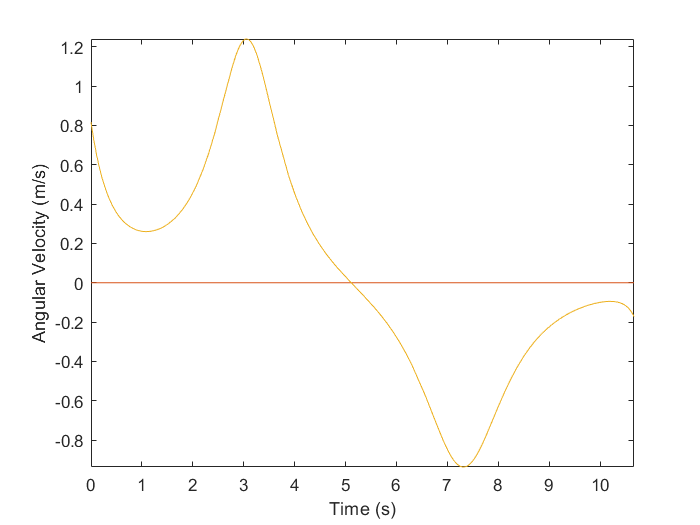

clf;
fplot(angular_velocity,[0 3.2/beta])
xlabel('Time (s)')
ylabel('Angular Velocity (m/s)')

### Plot Left and Right Wheel Velocities

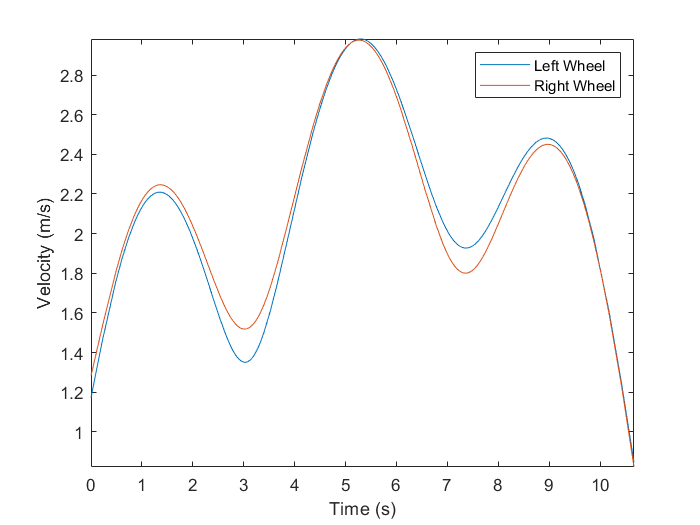

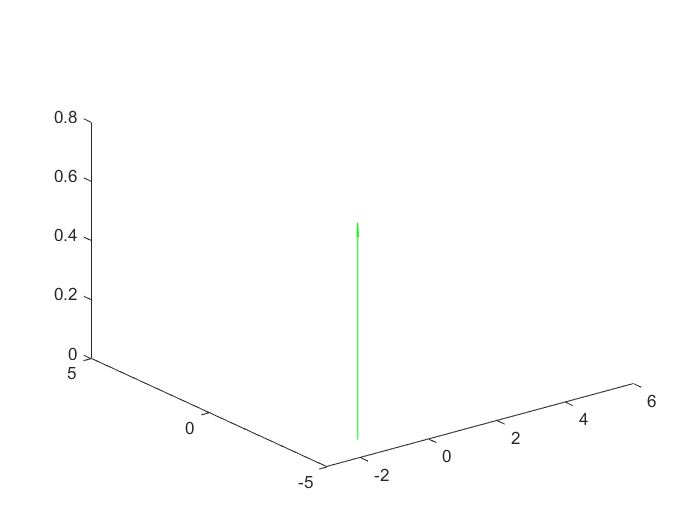

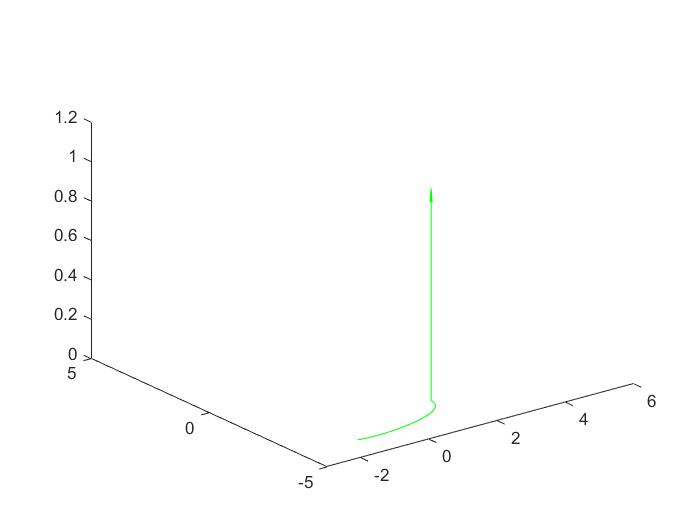

clf; 
fplot(norm(v_left_wheel),[0 3.2/beta]); hold on;
fplot(norm(v_right_wheel),[0 3.2/beta]); hold off;

xlabel('Time (s)')
ylabel('Velocity (m/s)')
legend('Left Wheel', 'Right Wheel')

data = 321×3 table
    time     encoderLeft    encoderRight
    _____    ___________    ____________

    912.4      126.04          126.11   
    912.5      126.04          126.11   
    912.6      126.04          126.11   
    912.7      126.04          126.11   
    912.8      126.04          126.11   
    912.9      126.06          126.14   
      913      126.08          126.17   
    913.1       126.1           126.2   
    913.2      126.13          126.22   
    913.3      126.15          126.25   
    913.4      126.18          126.28   
    913.5       126.2          126.31   
    913.6      126.23          126.35   
    913.7      126.26          126.38   
    913.8      126.29          126.41   
    913.9      126.32          126.44   


data_size = 321

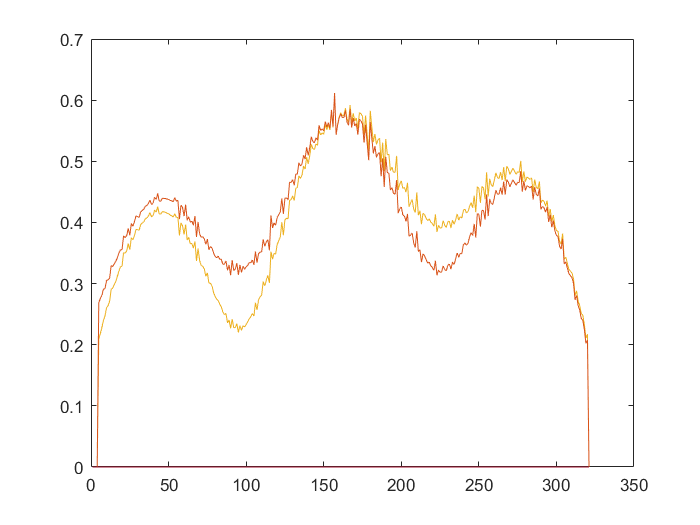

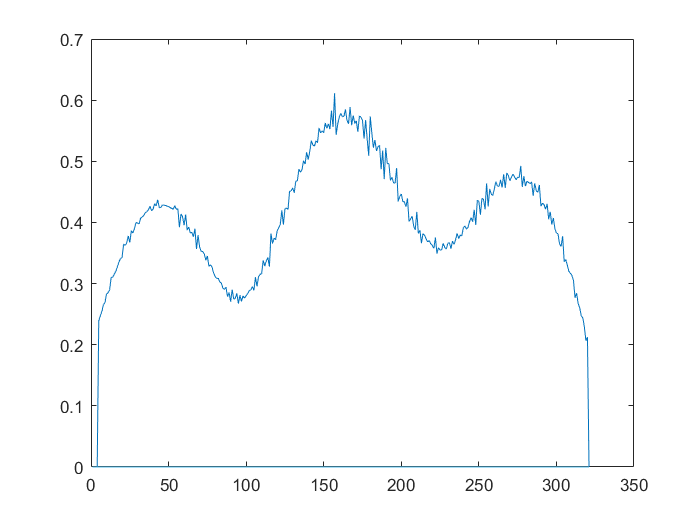

hold on;
plot(v_left_actual); hold on;
plot(v_right_actual); hold off;

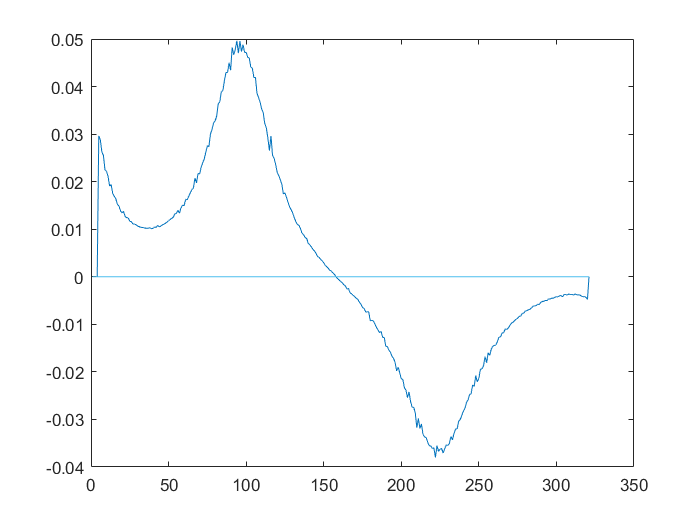

plot(angular_velocity_actual)